## POSTLAB #4 MATLAB CODE AUTHOR: TOMOKI KOIKE

clear all 
close all
clc

% Loading the data files 
file1 = readmatrix('calbration.xlsx');
file2 = readmatrix('smoothCylinder.xlsx');
file3 = readmatrix('roughCylinder.xlsx');
file4 = readmatrix("streamlinedBody.xlsx");

% Setting necessary constants
rho = 1.225;  % Desity of air at standard condition [kg/m^3]
visc = 1.789*10^(-5);  % Viscosity of air at standard conditions [Pa-s]

## 1.

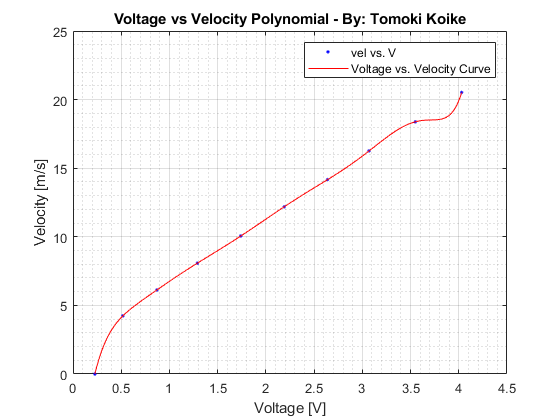

% First we must fit the voltage vs velocity curve to a polynomial function 
% Extracting columns from the first file and assigning them to variables 
dynP = file1(:,2);  % Dynamic pressure [kPa]
dynP = dynP*1000;  % Convert pressure to Pa [Pa]
V = file1(:,3);  % Voltages [V]

% Calculating the velocities from the dynamic pressures 
vel = sqrt(2*dynP/rho);

% Now fit the curve using function
[fitresult, gof] = vel_vs_vol_Fit(V, vel);

disp(fitresult);

     Linear model Poly9:
     fitresult(x) = p1*x^9 + p2*x^8 + p3*x^7 + p4*x^6 + 
                    p5*x^5 + p6*x^4 + p7*x^3 + p8*x^2 + p9*x + p10
     Coefficients:
       p1 =       0.121
       p2 =      -2.253
       p3 =       17.85
       p4 =      -78.84
       p5 =       212.9
       p6 =      -363.9
       p7 =       393.2
       p8 =      -259.7
       p9 =       100.6
       p10 =       -13.2


gof_mat = cell2mat(struct2cell(gof));  % Convert structure to matrix
% Printing out the standard deviation for this polynomial
fprintf('\nThis fitted polynomial curve has a STD of %.5e.', gof_mat(1,1));  


This fitted polynomial curve has a STD of 6.70372e-22.

coeffs = coeffvalues(fitresult);  % Obtaining the coefficients 
% Assigning the coefficient values to variables
c9 = coeffs(1);
c8 = coeffs(2);
c7 = coeffs(3);
c6 = coeffs(4);
c5 = coeffs(5);
c4 = coeffs(6);
c3 = coeffs(7);
c2 = coeffs(8);
c1 = coeffs(9);
c0 = coeffs(10);

% Defining the polynomial system for voltage vs velocity 
syms E
vel = @(E) c0 + c1*E + c2*E.^2 + c3*E.^3 + c4*E.^4 + c5*E.^5 ...
    + c6*E.^6 + c7*E.^7 + c8*E.^8 + c9*E.^9;

% Defining the symbolic equation for Reynold's number
syms Velocity
Re = @(Velocity,d) rho.*Velocity*d/visc;

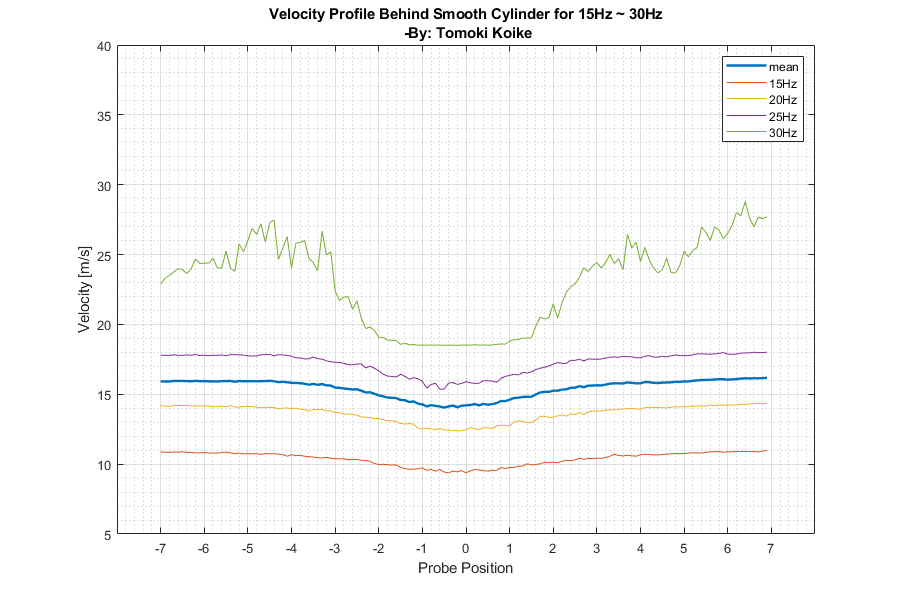

% Datas from the smooth cylinder data file is going to be used for this
% section 

% Extracting data columns and assigning them to variables
y = file2(:,1);  % The positions, y
Vsmooth15 = file2(:,2);  % The votages for 15 Hz
Vsmooth20 = file2(:,4);  % The voltages for 20 Hz
Vsmooth25 = file2(:,6);  % The voltages for 25 Hz
Vsmooth30 = file2(:,8);  % The voltages for 30 Hz
Vsmooth_all = [Vsmooth15, Vsmooth20, Vsmooth25, Vsmooth30];
std_smooth15 = file2(:,3);  % The standard deviations for 15 Hz
std_smooth20 = file2(:,5);  % The standard deviations for 20 Hz
std_smooth25 = file2(:,7);  % The standard deviations for 25 Hz
std_smooth15 = file2(:,9);  % The standard deviations for 30 Hz

% Calculating the velocities
vel_smooth15 = vel(Vsmooth15);
vel_smooth20 = vel(Vsmooth20);
vel_smooth25 = vel(Vsmooth25);
vel_smooth30 = vel(Vsmooth30);
vel_smooth_mean = vel(mean(Vsmooth_all,2));  % Mean

% Calculating the Reynold's numbers
% Re_smooth15 = Re(vel_smooth15,d);
% Re_smooth20 = Re(vel_smooth20,d);
% Re_smooth25 = Re(vel_smooth25,d);
% Re_smooth30 = Re(vel_smooth30,d);
% Re_smooth_mean = Re(vel_smooth_mean);  % Mean

% Calculating the velocity deficit
vel_smooth15_dfc = vel_deficit(find_u_inf(vel_smooth15), vel_smooth15);
vel_smooth20_dfc = vel_deficit(find_u_inf(vel_smooth20), vel_smooth20);
vel_smooth25_dfc = vel_deficit(find_u_inf(vel_smooth25), vel_smooth25);
vel_smooth30_dfc = vel_deficit(find_u_inf(vel_smooth30), vel_smooth30);
vel_smooth_mean_dfc = vel_deficit(find_u_inf(vel_smooth_mean), vel_smooth_mean);  

% Plotting 
% Velocities
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(y, vel_smooth_mean, '-', 'LineWidth', 1.8)
xlabel('Probe Position')
ylabel('Velocity [m/s]')
title({'Velocity Profile Behind Smooth Cylinder for 15Hz ~ 30Hz', [' -By:' ...
    ' Tomoki Koike']})
hold on
plot(y, vel_smooth15)
plot(y, vel_smooth20)
plot(y, vel_smooth25)
plot(y, vel_smooth30)
hold off
grid on 
grid minor
box on
xticks([-7:7])
ylim([5 40])
legend('mean', '15Hz', '20Hz', '25Hz', '30Hz')

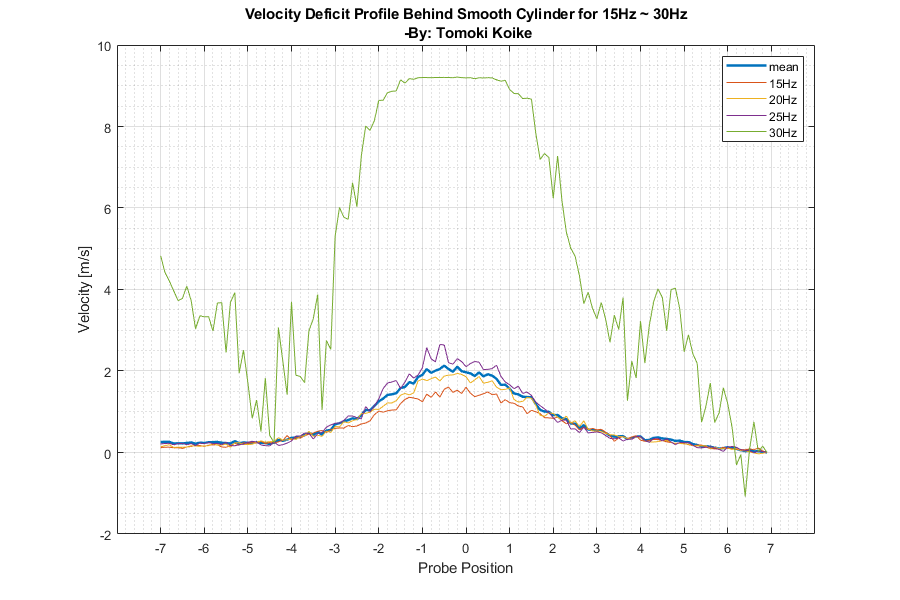

% Plotting velocity deficit
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(y, vel_smooth_mean_dfc, '-', 'LineWidth', 1.8)
xlabel('Probe Position')
ylabel('Velocity [m/s]')
title({'Velocity Deficit Profile Behind Smooth Cylinder for 15Hz ~ 30Hz', [' -By:' ...
    ' Tomoki Koike']})
hold on
plot(y, vel_smooth15_dfc)
plot(y, vel_smooth20_dfc)
plot(y, vel_smooth25_dfc)
plot(y, vel_smooth30_dfc)
hold off
grid on 
grid minor
box on
xticks([-7:7])
legend('mean', '15Hz', '20Hz', '25Hz', '30Hz')

## 2.

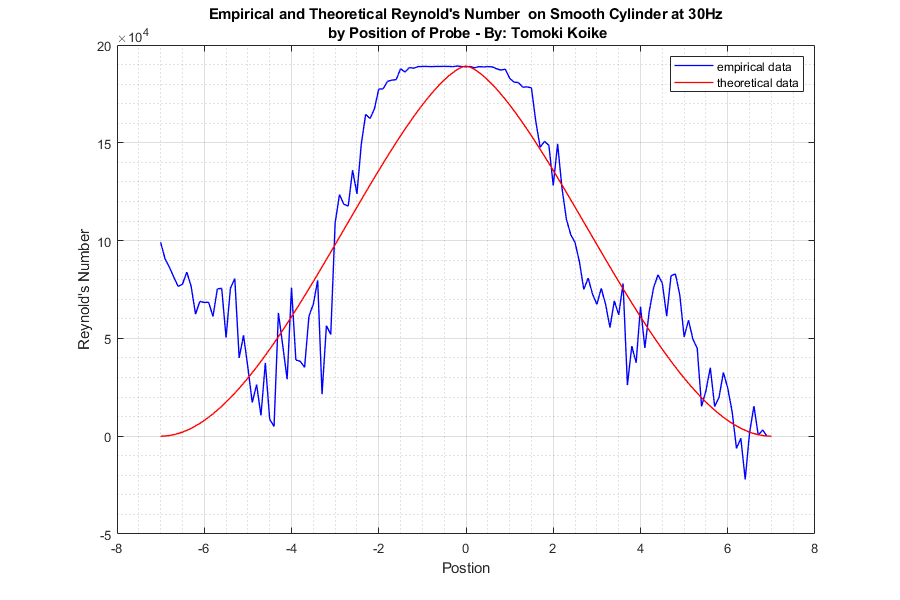

% Calculating the drags using a theoretical method for 30Hz
syms ys
% constants
u1_max = max(vel_smooth30_dfc);  % The maximum velocity deficit 
b = 7;  % Range of which probe moved sideways
h = pi^2/4;  
% Symbolic equation to solve for the velocity deficit distribution 
u1_n = @(ys) u1_max*(1 - (-ys/b).^(3/2)).^2;
u1_p = @(ys) u1_max*(1 - (ys/b).^(3/2)).^2;

% Acutally calcualting the velocity deficit theoretically 
y_n = -7:0.1:0;
y_p = 0.1:0.1:7.0;
u1_n = u1_n(y_n)';
u1_p = u1_p(y_p)'; 
u1 = [u1_n; u1_p];

% Now compute the Reynold's number using the velocity deficit for the
% empirical and theoretical values 
Re_emp = Re(vel_smooth30_dfc,0.3);  % Empirical method
Re_the = Re(u1,0.3);  % Theoretical method

% Plotting the Reynold's number
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(y, Re_emp, '-b', 'LineWidth', 1)
xlabel('Postion')
ylabel('Reynold''s Number')
title({['Empirical and Theoretical Reynold''s Number ' ...
    ' on Smooth Cylinder at 30Hz'], ['' ...
    ' by Position of Probe - By: Tomoki Koike']})
hold on
plot(y, Re_the, '-r', 'LineWidth', 1)
hold off
grid on
grid minor
box on
legend('empirical data', 'theoretical data')


% Next compute the drag using both empirical and theoretical velocity
% deficit
D_emp = dragCal(rmmissing(vel_smooth30_dfc), find_u_inf(vel_smooth30));  % Empirical
D_the = dragCal(u1, find_u_inf(vel_smooth30));  % Theoretical

fprintf('--------The drags computed for each methods--------');

--------The drags computed for each methods--------

fprintf('Empirical:     %.4f N', D_emp);

Empirical:     13157.1533 N

fprintf('Theoretical:   %.4f N', D_the);

Theoretical:   11707.1541 N

## 3.

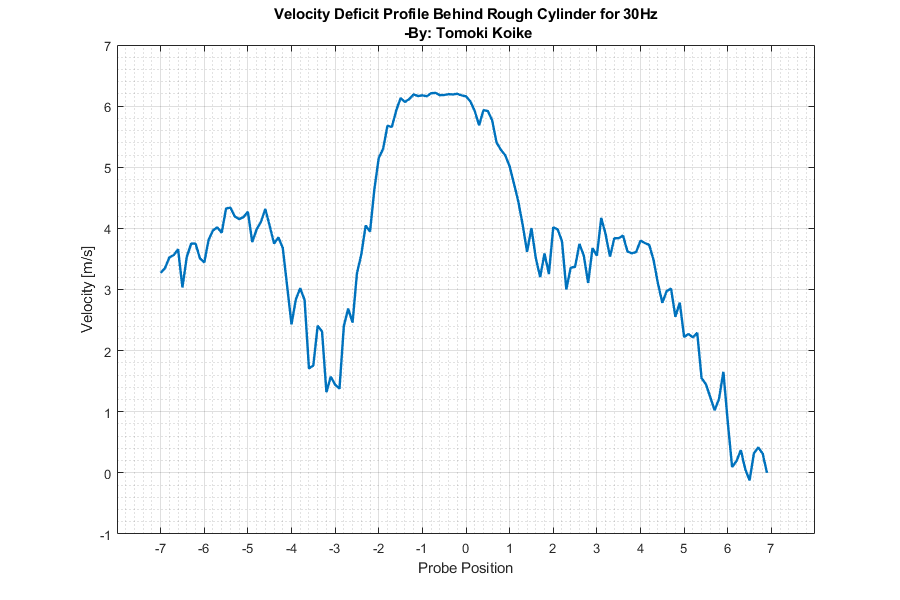

% Analyzing the rough cylinder and the streamlined body
% Rough Cylinder
Vrough30 = file3(:,8);  % The voltages for 30 Hz

% Calculating the velocities
vel_rough30 = vel(Vrough30);

% Calculating the velocity deficit
vel_rough30_dfc = vel_deficit(find_u_inf(vel_rough30), vel_rough30);

% Streamlined body
Vstream30 = file4(:,8);

% Calculating the velocities
vel_stream30 = vel(Vstream30);

% Calculating the velocity deficit
vel_stream30_dfc = vel_deficit(find_u_inf(vel_stream30), vel_stream30);

% Plotting
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(y, vel_rough30_dfc, '-', 'LineWidth', 1.8)
xlabel('Probe Position')
ylabel('Velocity [m/s]')
title({'Velocity Deficit Profile Behind Rough Cylinder for 30Hz', [' -By:' ...
    ' Tomoki Koike']})
grid on 
grid minor
box on
xticks([-7:7])

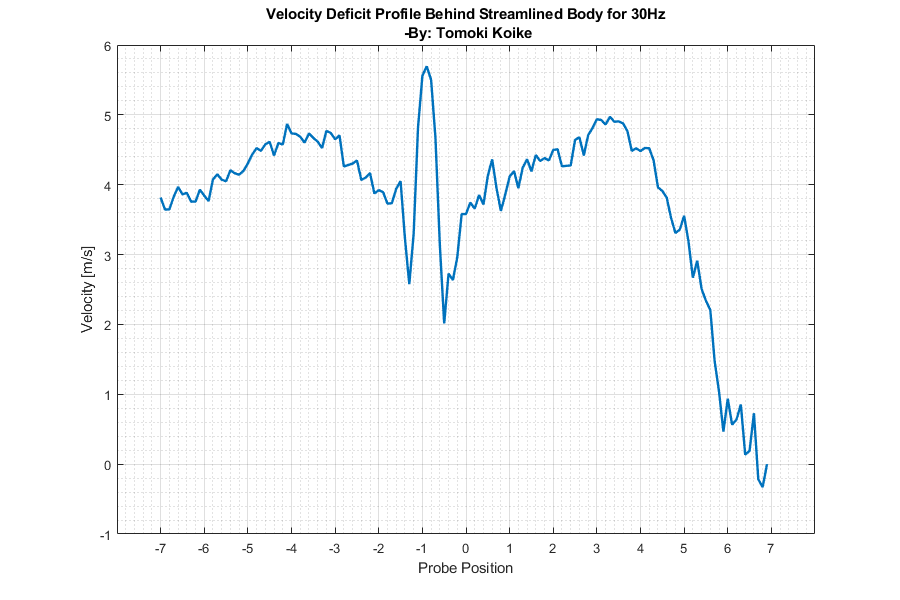


figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(y, vel_stream30_dfc, '-', 'LineWidth', 1.8)
xlabel('Probe Position')
ylabel('Velocity [m/s]')
title({'Velocity Deficit Profile Behind Streamlined Body for 30Hz', [' -By:' ...
    ' Tomoki Koike']})
grid on 
grid minor
box on
xticks([-7:7])

## FUNCTIONS

function U_df = vel_deficit(U_inf, u)
    % This function calculates the velocity deficit
    U_df = U_inf - u;
end 

function U_inf = find_u_inf(u)
    % This function finds the U_inf from the positions 7 or -7
    if u(1) >= u(end-1)
        U_inf = u(1);
    else
        U_inf = u(end-1);
    end
end

function D = dragCal(u1, u_inf)
    % constants 
    h = pi/4;
    rho = 1.225;
    
    u1_n = u1(1:71,1);
    u1_p = u1(72:end,1);
    D_n = u1_n.*(u_inf - u1_n);
    D_p = u1_p.*(u_inf - u1_p);
    D = h*rho*trapz(D_n) + h*rho*trapz(D_p);
end

function [fitresult, gof] = vel_vs_vol_Fit(V, vel)
    %VEL_VS_VOL_FIT(V,VEL)
    %  Create a fit.
    %  Data for 'Voltage vs. Velocity Curve' fit:
    %      X Input : V
    %      Y Output: vel
    %  Output:
    %      fitresult : a fit object representing the fit.
    %      gof : structure with goodness-of fit info.
    %
    %% Fit: 'Voltage vs. Velocity Curve'.
    [xData, yData] = prepareCurveData( V, vel );
    
    % Set up fittype and options.
    ft = fittype( 'poly9' );
    
    % Fit model to data.
    [fitresult, gof] = fit( xData, yData, ft );
    
    % Plot fit with data.
    figure('Renderer', 'painters', 'Position', [10 10 900 600])
    figure( 'Name', 'Voltage vs. Velocity Curve' );
    h = plot( fitresult, xData, yData );
    title('Voltage vs Velocity Polynomial - By: Tomoki Koike')
    legend( h, 'vel vs. V', 'Voltage vs. Velocity Curve', 'Location', ['' ...
        'NorthEast'], 'Interpreter', 'none' );
    % Label axes
    xlabel( 'Voltage [V]', 'Interpreter', 'none' );
    ylabel( 'Velocity [m/s]', 'Interpreter', 'none' );
    grid on
    grid minor
    box on
end